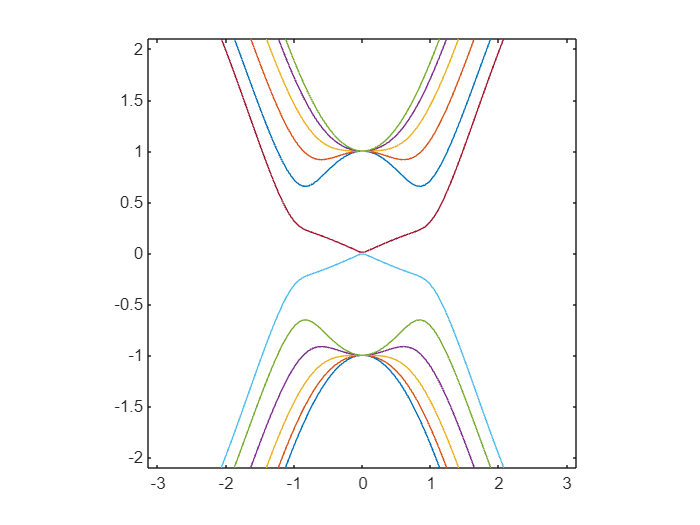

nkx = 100;
kx = linspace(-pi,pi,nkx);
t = 1;
D = 0.3;
mu = -2;
gamma = -0.5;

N = 6; % number of chains in y direction


X = [0,1;1,0]; Y = [0,-1i;1i,0]; Z = [1,0;0,-1]; I = eye(2);
p = @(m,n) proj(m,n,N);

Spec = zeros(2*N,nkx);
for nk = 1:nkx
    % construct Hamiltonian
    H = zeros(2*N);
    k = kx(nk);
    for i = 1:N
        H = H - gamma * kron((Z + 1i*X), p(i,i+1));
        H = H - gamma * kron((Z - 1i*X), p(i+1,i));
        H = H + kron(-(2*t*cos(k)+mu)*Z + D*sin(k)*Y, p(i,i));
    end
    [~,lam] = eig(H,'vector');
    lam = sort(lam);
    Spec(:,nk) = lam;
end

plot(kx,Spec)
ylim([-2.1,2.1])
xlim([-pi,pi])
pbaspect([1,1,1])

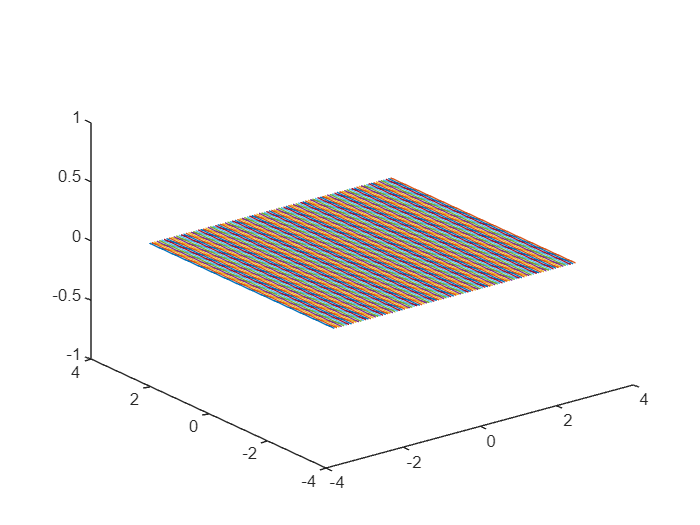


% 3D case - Weyl semimetal

% add another dimension:
kz = linspace(-pi,pi,nkx);
k0 = pi/3;

% hopping parameters
tx = 1;
ty = 1;
tz = 1;
m = 10;

% same N = 6;
Spec = zeros(nkx,nkx,2*N);
for ikx = 1:nkx
    for ikz = 1:nkx
        H = zeros(2*N);
        k1 = kx(ikx);
        k2 = kz(ikz);
        for i = 1:N
            H = H + kron((2*tz*(cos(k0)-cos(k2))+m*(2-cos(k1)))*Z + 2*tx*sin(k1)*X, p(i,i));
            H = H + kron(-m/2*Z+1i*ty*X, p(i,i+1));
            H = H + kron(m/2*Z-1i*ty*X, p(i+1,i));
        end
    end
end
[Xmesh,Ymesh] = meshgrid(kx,kz);

surf(Xmesh,Ymesh,Spec(:,:,4))

function p = proj(m,n,N)
if (m>0) && (m<=N) && (n>0) && (n<=N)
    p = zeros(N);
    p(m,n) = 1;
else % for open boundaries
    p = zeros(N);
end
end